function [L direction po]=Map(Mode,a)
% Mode.map = 3 ;
switch Mode.map
    case 1
        sx=[4 12 12.5 13.5 14 43.3]*1000;
        ss.y=[-10 0 7 0 -7 0];
        syms thetas
        n=size(sx,2);
        ss.x=sx-[0,sx(1:n-1)];
        for i=1:size(sx,2)
            eqn1=sin(thetas)==ss.y(i)./ss.x(i)/1000;
            thetaa(i)=min(double(solve(eqn1,thetas)));
        end
        direction=deg2rad([80 195 270 180 0 180]);
        L=[ss.x
            thetaa
            zeros(1,n)
            direction];
    case 10
        sx=[4 12 12.5 13.5 14 43.3]*1000*303/433;
        ss.y=[-10 0 7 0 -7 0];
        syms thetas
        n=size(sx,2);
        ss.x=sx-[0,sx(1:n-1)];
        for i=1:size(sx,2)
            eqn1=sin(thetas)==ss.y(i)./ss.x(i)/1000;
            thetaa(i)=min(double(solve(eqn1,thetas)));
        end
        direction=deg2rad([80 195 270 180 0 180]);
        L=[ss.x
            thetaa
            zeros(1,n)
            direction];
    case 2
        % 日奥
        L=[2.5	5	5.05	9.5	9.55	10.5	10.51	15	15.05	15.5	17	17.05	17.5	19	19.05	20	20.05	22.1
            -30	20	20	-25	-25	-25	-25	-25	1	1	25	25	1	1	1	1	1	1
            0	0	0	1	0	1	0	1	0	0	1	0	0	1	0	1	0	0
            120	150	280	280	290	40	65	65	65	30	30	0	230	140	50	50	50	50];
        L(1,:)=L(1,:)*10^3;
        L(2,:)=deg2rad(L(2,:))*0.1;
        direction = [];
    case 3
        L=[2.5	5	5.05	9.5	9.55	10.5	10.51	15	15.05	15.5	17	17.05	17.5	19	19.05	20	20.05	22.1	24.6	27.1	27.15	31.6	31.65	32.6	32.61	37.1	37.15	37.6	39.1	39.15	39.6	41.1	41.15	42.1	42.15	44.2
            -30	20	20	-25	-25	-25	-25	-25	1	1	35	35	1	1	1	1	1	1	-30	20	20	-25	-25	-25	-25	-25	1	1	35	35	1	1	1	1	1	1
            0	0	0	1	0	1	0	1	0	0	1	0	0	1	0	1	0	0	0	0	0	1	0	1	0	1	0	0	1	0	0	1	0	1	0	0
            120	150	280	280	290	40	65	65	65	30	30	0	230	140	50	50	50	50	120	150	280	280	290	40	65	65	65	30	30	0	230	140	50	50	50	50
            ];
        for i=1:size(L,2)
            if L(2,i)>1
                po(i)=1;
            elseif L(2,i)==1
                po(i)=0;
            else po(i)=-1;
            end
        end
        L(1,:)=L(1,:)*10^3;
        L(2,:)=deg2rad(L(2,:))*0.1;
        direction = [];
    case 0
        if exist('a')==0
            a=6;
        end
        b=0.05;
        podu=2;

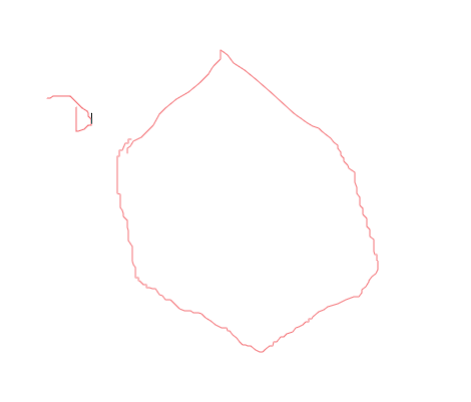

        L=[a    a+b 2*a     2*a+b   3*a  3*a+b   4*a    4*a+b 5*a    5*a+b    6*a
            1/1000   1/1000 podu  1/1000    -podu      1/1000       1/1000 1/1000 podu  1/1000                 -podu    
            0   1   0       1       0   1       0       1   0       1       0
            60  90  120     150     180 210     240     270    300     330     0];
        L(1,:)=L(1,:)*10^3;
        L(2,:)=deg2rad(L(2,:))/15;
        clear x;x=sqrt(3);
        direction=[x	1
            x	0
            x	-1
            1	-x
            0	-1
            -1	-x
            -x	-1
            -x	0
            -x	1
            1	x
            0	1]';
        po='un';
end
end